AL8843 Calculations

clear all
close all
L = 33 * 10^-6;
Iled = 3;
Iripple = 0.4 * Iled;
Vin = 24;
Vled = [3.05 3.65];
Rs = 0.033;
Rl = 0.2;
Rsw = 0.3;
Vd = 0.8;
min_on_time = 500 * 10^-9;
t_on = L * Iripple ./ (Vin - Vled - Iled * (Rs+Rl+Rsw));
t_on_longer_than_min = t_on > min_on_time

t_on_longer_than_min = 1×2 logical array
   1   1


t_off = L * Iripple ./ (Vled + Vd + Iled * (Rs+Rl));
f_sw_kHz = 1./(t_on+t_off) / 1000

f_sw_kHz =    93.0093  102.0127


f_sw_below_max = f_sw_kHz < 1000

f_sw_below_max = 1×2 logical array
   1   1


D = t_on ./ (t_on + t_off)

D =     0.1903    0.2154


D_below_max = D < 0.98

D_below_max = 1×2 logical array
   1   1


Switch_power_dissipation = Iripple^2 * Rsw

Switch_power_dissipation = 0.4320

NTC Thermistor Calculations

T = 2:125;

T =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51


Rt = 1000 .* [25.177	24.124	23.121	22.165	21.253	20.384	19.555	18.764	18.01	17.29	16.602	15.946	15.319	14.72	14.148	13.601	13.078	12.578	12.099	11.642	11.204	10.785	10.384	10	9.632	9.28	8.943	8.619	8.309	8.012	7.727	7.453	7.191	6.939	6.698	6.466	6.243	6.029	5.824	5.627	5.437	5.255	5.08	4.911	4.749	4.593	4.443	4.299	4.16	4.027	3.898	3.774	3.654	3.539	3.429	3.322	3.219	3.119	3.024	2.931	2.842	2.756	2.673	2.593	2.516	2.441	2.369	2.3	2.233	2.168	2.105	2.044	1.986	1.929	1.874	1.821	1.77	1.72	1.673	1.626	1.581	1.538	1.496	1.455	1.416	1.377	1.34	1.304	1.27	1.236	1.204	1.172	1.141	1.112	1.083	1.055	1.028	1.002	0.976	0.951	0.927	0.904	0.882	0.86	0.838	0.818	0.798	0.778	0.759	0.741	0.723	0.706	0.689	0.673	0.657	0.641	0.626	0.612	0.598	0.584	0.57	0.557	0.545	0.532];
Vout = 3.3 * Rt./(Rt+4700);
plot(T,Vout)
xlim([0 80])
ylabel("NTC V_o_u_t(V)")
xlabel("Temperature (deg C)")
grid on
title("Thermistor Output vs temperature")
hold on
Tnew = T(1:80)

Tnew =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51


X = [ones(length(Tnew'),1), Tnew'];
Voutnew = Vout(1:80)

Voutnew =     2.7809    2.7619    2.7425    2.7227    2.7024    2.6817    2.6605    2.6390    2.6170    2.5947    2.5719    2.5488    2.5252    2.5013    2.4771    2.4525    2.4276    2.4023    2.3767    2.3509    2.3248    2.2984    2.2718    2.2449    2.2178    2.1906    2.1632    2.1355    2.1077    2.0799    2.0519    2.0238    1.9957    1.9674    1.9392    1.9110    1.8827    1.8544    1.8262    1.7981    1.7700    1.7420    1.7141    1.6862    1.6586    1.6310    1.6036    1.5765    1.5494    1.5228


b = X \ Voutnew'

b =     2.8672
   -0.0258


temp_linfit = b(1) + b(2).*T

temp_linfit =     2.8157    2.7899    2.7641    2.7384    2.7126    2.6868    2.6610    2.6353    2.6095    2.5837    2.5580    2.5322    2.5064    2.4806    2.4549    2.4291    2.4033    2.3775    2.3518    2.3260    2.3002    2.2744    2.2487    2.2229    2.1971    2.1713    2.1456    2.1198    2.0940    2.0683    2.0425    2.0167    1.9909    1.9652    1.9394    1.9136    1.8878    1.8621    1.8363    1.8105    1.7847    1.7590    1.7332    1.7074    1.6817    1.6559    1.6301    1.6043    1.5786    1.5528


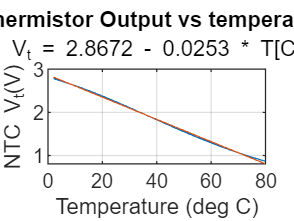

plot(T,temp_linfit)
subtitle(["V_{out} = 2.8672 - 0.0253 * T[" char(176) "C]"])
hold off